shape function $l = \varphi_i(x,y,z)$: tuyến tính, bằng 1 tại nút i, bằng 0 tại các nút còn lại.


$$\varphi_i(x,y,z) = a_ix+b_iy+c_iz+di.$$


Một phần tử có hình tứ diện gồm 4 đỉnh là $A_i(x_i,y_i,z_i), i=1,2,3,4.$

dạng ma trận khi thay lần lượt các điều kiện trên

$\left\lbrack \begin{array}{cccc}
1 & x_1  & y_1  & z_1 \\
1 & x_2  & y_2  & z_2 \\
1 & x_3  & y_3  & z_3 \\
1 & x_4  & y_4  & z_4 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{cccc}
d_1  & d_2  & d_3  & d_4 \\
a_1  & a_2  & a_3  & a_4 \\
b_1  & b_2  & b_3  & b_4 \\
c_1  & c_2  & c_3  & c_4 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$(PQ=E)

Chú ý: Q là ma trận nghịch đảo của P.

syms x1 y1 z1 x2 y2 z2 x3 y3 z3 x4 y4 z4
P = [1 x1 y1 z1;...
     1 x2 y2 z2;...
     1 x3 y3 z3;...
     1 x4 y4 z4]

$$P = \left(\begin{array}{cccc} 1 & x_{1} & y_{1} & z_{1}\\ 1 & x_{2} & y_{2} & z_{2}\\ 1 & x_{3} & y_{3} & z_{3}\\ 1 & x_{4} & y_{4} & z_{4} \end{array}\right)$$

 Q = inv(P)

 d1 = det(P(2:4,2:4))

$$d1 = x_{2}\,y_{3}\,z_{4}-x_{2}\,y_{4}\,z_{3}-x_{3}\,y_{2}\,z_{4}+x_{3}\,y_{4}\,z_{2}+x_{4}\,y_{2}\,z_{3}-x_{4}\,y_{3}\,z_{2}$$

det(P([2,3,4],[1,3,4]))

$$ans = y_{2}\,z_{3}-y_{3}\,z_{2}-y_{2}\,z_{4}+y_{4}\,z_{2}+y_{3}\,z_{4}-y_{4}\,z_{3}$$

Chú ý: $\sigma_1 = \det(P).$

Tìm một phép đổi biến để biến tứ diện $A_1 A_2 A_3 A_4 \;$ thành tứ diện vuông tại gốc tọa độ $OMNP$ với $O(0,0,0), M(1,0,0), N(0,1,0), P(0,0,1).$ Chuyển hệ tọa độ (x,y,z) thành hệ tọa độ $\varepsilon_1, \varepsilon_2, \varepsilon_3.$

Ma trận Jacobian $J=\left\lbrack \begin{array}{ccc}
\vec{A_1 A_2 }  & \vec{A_1 A_3 }  & \vec{A_1 A_4 } 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{ccc}
x_2 -x_1  & x_3 -x_1  & x_4 -x_1 \\
y_2 -y_1  & y_3 -y_1  & y_4 -y_1 \\
z_2 -z_1  & z_3 -z_1  & z_4 -z_1 
\end{array}\right\rbrack$

J = [x2-x1,x3-x1, x4-x1;...
     y2-y1,y3-y1, y4-y1;...
     z2-z1,z3-z1, z4-z1;]

$$J = \left(\begin{array}{ccc} x_{2}-x_{1} & x_{3}-x_{1} & x_{4}-x_{1}\\ y_{2}-y_{1} & y_{3}-y_{1} & y_{4}-y_{1}\\ z_{2}-z_{1} & z_{3}-z_{1} & z_{4}-z_{1} \end{array}\right)$$

det(J)

$$ans = x_{1}\,y_{3}\,z_{2}-x_{1}\,y_{2}\,z_{3}+x_{2}\,y_{1}\,z_{3}-x_{2}\,y_{3}\,z_{1}-x_{3}\,y_{1}\,z_{2}+x_{3}\,y_{2}\,z_{1}+x_{1}\,y_{2}\,z_{4}-x_{1}\,y_{4}\,z_{2}-x_{2}\,y_{1}\,z_{4}+x_{2}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{2}-x_{4}\,y_{2}\,z_{1}-x_{1}\,y_{3}\,z_{4}+x_{1}\,y_{4}\,z_{3}+x_{3}\,y_{1}\,z_{4}-x_{3}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{3}+x_{4}\,y_{3}\,z_{1}+x_{2}\,y_{3}\,z_{4}-x_{2}\,y_{4}\,z_{3}-x_{3}\,y_{2}\,z_{4}+x_{3}\,y_{4}\,z_{2}+x_{4}\,y_{2}\,z_{3}-x_{4}\,y_{3}\,z_{2}$$

Giá trị của det(P) = sigma_1 = det(J)

det(J) - det(P)

$$ans = 0$$

Khi đó ánh xạ tuyến tính biến đổi OMNP thành $A_1 A_2 A_3 A_4 \;\;\textrm{là}$ $l\left(\varepsilon ,\zeta ,\eta \right)={\left(x,y,z\right)}^{\prime } =\left(x_{1,\;} y_1 ,z_1 \right)\prime +J\left\lbrack \begin{array}{c}
\varepsilon \\
\zeta \\
\eta 
\end{array}\right\rbrack \ldotp$

 syms epsilon zeta eta
 l= [x1; y1; z1]+J*[epsilon;zeta;eta]

$$l = \left(\begin{array}{c} x_{1}-\epsilon \,\left(x_{1}-x_{2}\right)-\eta \,\left(x_{1}-x_{4}\right)-\zeta \,\left(x_{1}-x_{3}\right)\\ y_{1}-\epsilon \,\left(y_{1}-y_{2}\right)-\eta \,\left(y_{1}-y_{4}\right)-\zeta \,\left(y_{1}-y_{3}\right)\\ z_{1}-\epsilon \,\left(z_{1}-z_{2}\right)-\eta \,\left(z_{1}-z_{4}\right)-\zeta \,\left(z_{1}-z_{3}\right) \end{array}\right)$$

 syms epsilon zeta eta
 subs(l,{epsilon ,zeta ,eta},{0,0,0})

$$ans = \left(\begin{array}{c} x_{1}\\ y_{1}\\ z_{1} \end{array}\right)$$

 subs(l,{epsilon ,zeta ,eta},{1,0,0})

$$ans = \left(\begin{array}{c} x_{2}\\ y_{2}\\ z_{2} \end{array}\right)$$

 subs(l,{epsilon ,zeta ,eta},{0,1,0})

$$ans = \left(\begin{array}{c} x_{3}\\ y_{3}\\ z_{3} \end{array}\right)$$

 subs(l,{epsilon ,zeta ,eta},{0,0,1})

$$ans = \left(\begin{array}{c} x_{4}\\ y_{4}\\ z_{4} \end{array}\right)$$

Tính được $a_i ,b_i ,c_i ,d_i \;\;\textrm{với}\;i=1,2,3,4\ldotp$ Khi đó biết được công thức của 4 shape functions $\;\varphi_1 ,\varphi_2 ,\varphi_3 ,\varphi_4 \ldotp$

Ma trận để cập nhật kích cỡ 4x4: M_local = $\left(M_{\textrm{ij}} \right)\;\textrm{với}\;M_{\textrm{ij}} =$$\int_{element \ A_1A_2A_3A_4} \varphi_i\varphi_j dxdydz.$

Sử dụng cách đổi biến như phía trên thành miền OMNP.

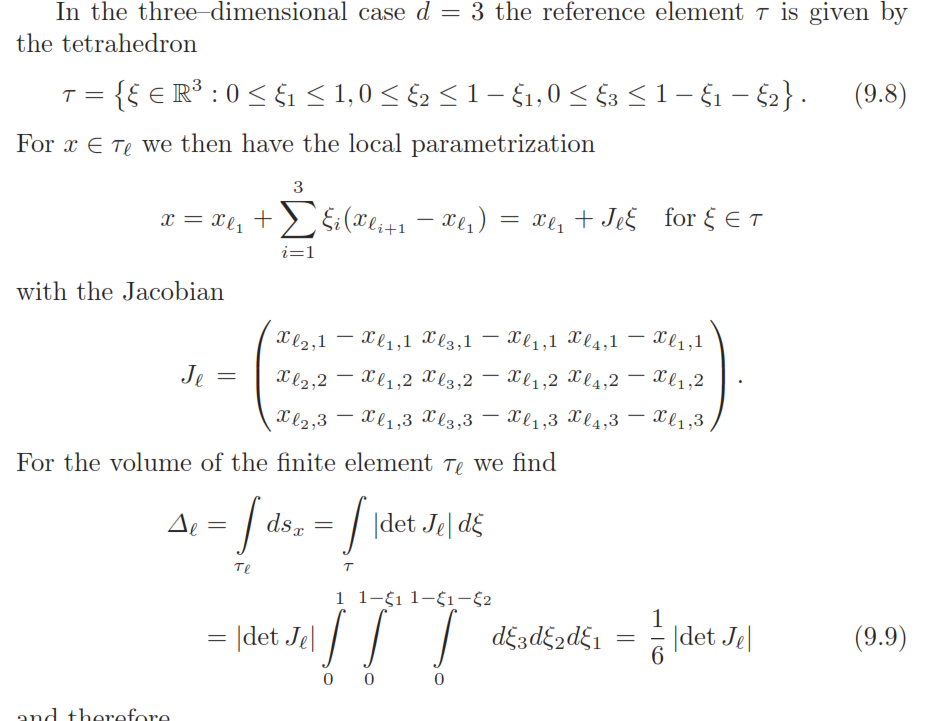


l(1)

$$ans = x_{1}-\epsilon \,\left(x_{1}-x_{2}\right)-\eta \,\left(x_{1}-x_{4}\right)-\zeta \,\left(x_{1}-x_{3}\right)$$

l(2)

$$ans = y_{1}-\epsilon \,\left(y_{1}-y_{2}\right)-\eta \,\left(y_{1}-y_{4}\right)-\zeta \,\left(y_{1}-y_{3}\right)$$

l(3)

$$ans = z_{1}-\epsilon \,\left(z_{1}-z_{2}\right)-\eta \,\left(z_{1}-z_{4}\right)-\zeta \,\left(z_{1}-z_{3}\right)$$

- Cấc hàm $\;\varphi_1 ,\varphi_2 ,\varphi_3 ,\varphi_4 \ldotp$

### Tính các hàm phi_i và các hàm f_i khi đổi tọa độ

syms x y z
phi_1 = [1, x, y, z]*Q(:,1), f_1=subs(phi_1,{x,y,z},{l(1),l(2),l(3)})

$$phi\_1 = \begin{array}{l} \frac{z\,\left(x_{2}\,y_{3}-x_{3}\,y_{2}-x_{2}\,y_{4}+x_{4}\,y_{2}+x_{3}\,y_{4}-x_{4}\,y_{3}\right)}{\sigma_{1}}-\frac{x_{2}\,y_{3}\,z_{4}-x_{2}\,y_{4}\,z_{3}-x_{3}\,y_{2}\,z_{4}+x_{3}\,y_{4}\,z_{2}+x_{4}\,y_{2}\,z_{3}-x_{4}\,y_{3}\,z_{2}}{\sigma_{1}}-\frac{y\,\left(x_{2}\,z_{3}-x_{3}\,z_{2}-x_{2}\,z_{4}+x_{4}\,z_{2}+x_{3}\,z_{4}-x_{4}\,z_{3}\right)}{\sigma_{1}}+\frac{x\,\left(y_{2}\,z_{3}-y_{3}\,z_{2}-y_{2}\,z_{4}+y_{4}\,z_{2}+y_{3}\,z_{4}-y_{4}\,z_{3}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

$$f\_1 = \begin{array}{l} \frac{\left(\epsilon \,\left(y_{1}-y_{2}\right)-y_{1}+\eta \,\left(y_{1}-y_{4}\right)+\zeta \,\left(y_{1}-y_{3}\right)\right)\,\left(x_{2}\,z_{3}-x_{3}\,z_{2}-x_{2}\,z_{4}+x_{4}\,z_{2}+x_{3}\,z_{4}-x_{4}\,z_{3}\right)}{\sigma_{1}}-\frac{\left(\epsilon \,\left(x_{1}-x_{2}\right)-x_{1}+\eta \,\left(x_{1}-x_{4}\right)+\zeta \,\left(x_{1}-x_{3}\right)\right)\,\left(y_{2}\,z_{3}-y_{3}\,z_{2}-y_{2}\,z_{4}+y_{4}\,z_{2}+y_{3}\,z_{4}-y_{4}\,z_{3}\right)}{\sigma_{1}}-\frac{x_{2}\,y_{3}\,z_{4}-x_{2}\,y_{4}\,z_{3}-x_{3}\,y_{2}\,z_{4}+x_{3}\,y_{4}\,z_{2}+x_{4}\,y_{2}\,z_{3}-x_{4}\,y_{3}\,z_{2}}{\sigma_{1}}-\frac{\left(\epsilon \,\left(z_{1}-z_{2}\right)-z_{1}+\eta \,\left(z_{1}-z_{4}\right)+\zeta \,\left(z_{1}-z_{3}\right)\right)\,\left(x_{2}\,y_{3}-x_{3}\,y_{2}-x_{2}\,y_{4}+x_{4}\,y_{2}+x_{3}\,y_{4}-x_{4}\,y_{3}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

phi_2 = [1, x, y, z]*Q(:,2), f_2=subs(phi_2,{x,y,z},{l(1),l(2),l(3)})

$$phi\_2 = \begin{array}{l} \frac{x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}}{\sigma_{1}}-\frac{z\,\left(x_{1}\,y_{3}-x_{3}\,y_{1}-x_{1}\,y_{4}+x_{4}\,y_{1}+x_{3}\,y_{4}-x_{4}\,y_{3}\right)}{\sigma_{1}}+\frac{y\,\left(x_{1}\,z_{3}-x_{3}\,z_{1}-x_{1}\,z_{4}+x_{4}\,z_{1}+x_{3}\,z_{4}-x_{4}\,z_{3}\right)}{\sigma_{1}}-\frac{x\,\left(y_{1}\,z_{3}-y_{3}\,z_{1}-y_{1}\,z_{4}+y_{4}\,z_{1}+y_{3}\,z_{4}-y_{4}\,z_{3}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

$$f\_2 = \begin{array}{l} \frac{x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}}{\sigma_{1}}+\frac{\left(\epsilon \,\left(x_{1}-x_{2}\right)-x_{1}+\eta \,\left(x_{1}-x_{4}\right)+\zeta \,\left(x_{1}-x_{3}\right)\right)\,\left(y_{1}\,z_{3}-y_{3}\,z_{1}-y_{1}\,z_{4}+y_{4}\,z_{1}+y_{3}\,z_{4}-y_{4}\,z_{3}\right)}{\sigma_{1}}-\frac{\left(\epsilon \,\left(y_{1}-y_{2}\right)-y_{1}+\eta \,\left(y_{1}-y_{4}\right)+\zeta \,\left(y_{1}-y_{3}\right)\right)\,\left(x_{1}\,z_{3}-x_{3}\,z_{1}-x_{1}\,z_{4}+x_{4}\,z_{1}+x_{3}\,z_{4}-x_{4}\,z_{3}\right)}{\sigma_{1}}+\frac{\left(\epsilon \,\left(z_{1}-z_{2}\right)-z_{1}+\eta \,\left(z_{1}-z_{4}\right)+\zeta \,\left(z_{1}-z_{3}\right)\right)\,\left(x_{1}\,y_{3}-x_{3}\,y_{1}-x_{1}\,y_{4}+x_{4}\,y_{1}+x_{3}\,y_{4}-x_{4}\,y_{3}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

phi_3 = [1, x, y, z]*Q(:,3), f_3=subs(phi_3,{x,y,z},{l(1),l(2),l(3)})

$$phi\_3 = \begin{array}{l} \frac{z\,\left(x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{4}+x_{4}\,y_{1}+x_{2}\,y_{4}-x_{4}\,y_{2}\right)}{\sigma_{1}}-\frac{x_{1}\,y_{2}\,z_{4}-x_{1}\,y_{4}\,z_{2}-x_{2}\,y_{1}\,z_{4}+x_{2}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{2}-x_{4}\,y_{2}\,z_{1}}{\sigma_{1}}-\frac{y\,\left(x_{1}\,z_{2}-x_{2}\,z_{1}-x_{1}\,z_{4}+x_{4}\,z_{1}+x_{2}\,z_{4}-x_{4}\,z_{2}\right)}{\sigma_{1}}+\frac{x\,\left(y_{1}\,z_{2}-y_{2}\,z_{1}-y_{1}\,z_{4}+y_{4}\,z_{1}+y_{2}\,z_{4}-y_{4}\,z_{2}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

$$f\_3 = \begin{array}{l} \frac{\left(\epsilon \,\left(y_{1}-y_{2}\right)-y_{1}+\eta \,\left(y_{1}-y_{4}\right)+\zeta \,\left(y_{1}-y_{3}\right)\right)\,\left(x_{1}\,z_{2}-x_{2}\,z_{1}-x_{1}\,z_{4}+x_{4}\,z_{1}+x_{2}\,z_{4}-x_{4}\,z_{2}\right)}{\sigma_{1}}-\frac{\left(\epsilon \,\left(x_{1}-x_{2}\right)-x_{1}+\eta \,\left(x_{1}-x_{4}\right)+\zeta \,\left(x_{1}-x_{3}\right)\right)\,\left(y_{1}\,z_{2}-y_{2}\,z_{1}-y_{1}\,z_{4}+y_{4}\,z_{1}+y_{2}\,z_{4}-y_{4}\,z_{2}\right)}{\sigma_{1}}-\frac{x_{1}\,y_{2}\,z_{4}-x_{1}\,y_{4}\,z_{2}-x_{2}\,y_{1}\,z_{4}+x_{2}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{2}-x_{4}\,y_{2}\,z_{1}}{\sigma_{1}}-\frac{\left(\epsilon \,\left(z_{1}-z_{2}\right)-z_{1}+\eta \,\left(z_{1}-z_{4}\right)+\zeta \,\left(z_{1}-z_{3}\right)\right)\,\left(x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{4}+x_{4}\,y_{1}+x_{2}\,y_{4}-x_{4}\,y_{2}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

phi_4 = [1, x, y, z]*Q(:,4), f_4=subs(phi_4,{x,y,z},{l(1),l(2),l(3)})

$$phi\_4 = \begin{array}{l} \frac{x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}}{\sigma_{1}}-\frac{z\,\left(x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{3}+x_{3}\,y_{1}+x_{2}\,y_{3}-x_{3}\,y_{2}\right)}{\sigma_{1}}+\frac{y\,\left(x_{1}\,z_{2}-x_{2}\,z_{1}-x_{1}\,z_{3}+x_{3}\,z_{1}+x_{2}\,z_{3}-x_{3}\,z_{2}\right)}{\sigma_{1}}-\frac{x\,\left(y_{1}\,z_{2}-y_{2}\,z_{1}-y_{1}\,z_{3}+y_{3}\,z_{1}+y_{2}\,z_{3}-y_{3}\,z_{2}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

$$f\_4 = \begin{array}{l} \frac{x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}}{\sigma_{1}}+\frac{\left(\epsilon \,\left(x_{1}-x_{2}\right)-x_{1}+\eta \,\left(x_{1}-x_{4}\right)+\zeta \,\left(x_{1}-x_{3}\right)\right)\,\left(y_{1}\,z_{2}-y_{2}\,z_{1}-y_{1}\,z_{3}+y_{3}\,z_{1}+y_{2}\,z_{3}-y_{3}\,z_{2}\right)}{\sigma_{1}}-\frac{\left(\epsilon \,\left(y_{1}-y_{2}\right)-y_{1}+\eta \,\left(y_{1}-y_{4}\right)+\zeta \,\left(y_{1}-y_{3}\right)\right)\,\left(x_{1}\,z_{2}-x_{2}\,z_{1}-x_{1}\,z_{3}+x_{3}\,z_{1}+x_{2}\,z_{3}-x_{3}\,z_{2}\right)}{\sigma_{1}}+\frac{\left(\epsilon \,\left(z_{1}-z_{2}\right)-z_{1}+\eta \,\left(z_{1}-z_{4}\right)+\zeta \,\left(z_{1}-z_{3}\right)\right)\,\left(x_{1}\,y_{2}-x_{2}\,y_{1}-x_{1}\,y_{3}+x_{3}\,y_{1}+x_{2}\,y_{3}-x_{3}\,y_{2}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

- **Ma trận để cập nhật kích cỡ 4x4: M_local = **$\left(M_{\textrm{ij}} \right)\;\textrm{với}\;M_{\textrm{ij}} =$$\int_{element \ A_1A_2A_3A_4} \varphi_i\varphi_j dxdydz.$

f_1*f_2 - f_1*f_3

det(J)

$$ans = x_{1}\,y_{3}\,z_{2}-x_{1}\,y_{2}\,z_{3}+x_{2}\,y_{1}\,z_{3}-x_{2}\,y_{3}\,z_{1}-x_{3}\,y_{1}\,z_{2}+x_{3}\,y_{2}\,z_{1}+x_{1}\,y_{2}\,z_{4}-x_{1}\,y_{4}\,z_{2}-x_{2}\,y_{1}\,z_{4}+x_{2}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{2}-x_{4}\,y_{2}\,z_{1}-x_{1}\,y_{3}\,z_{4}+x_{1}\,y_{4}\,z_{3}+x_{3}\,y_{1}\,z_{4}-x_{3}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{3}+x_{4}\,y_{3}\,z_{1}+x_{2}\,y_{3}\,z_{4}-x_{2}\,y_{4}\,z_{3}-x_{3}\,y_{2}\,z_{4}+x_{3}\,y_{4}\,z_{2}+x_{4}\,y_{2}\,z_{3}-x_{4}\,y_{3}\,z_{2}$$

Khi đổi biến từ miền ban đầu về miền OMNP,

Tích phân trên miền mới OMNP 


$$\int_0^1\int _{0}^{1-\epsilon}\int_{0}^{1-\epsilon- \zeta} \phi_i\phi_j d\epsilon d\zeta d\eta$$


Tìm biểu thức của hàm thử trong hệ tọa độ mới.

%M(1,1)
abs(det(J))*int(int(int(f_1*f_1,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{60}$$

%M(1,2) = M(2,1)
abs(det(J))*int(int(int(f_1*f_2,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{120}$$

%M(1,3) = M(3,1)
abs(det(J))*int(int(int(f_1*f_3,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{120}$$

abs(det(J))*int(int(int(f_1*f_2,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)- abs(det(J))*int(int(int(f_1*f_3,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = 0$$

%M(1,4) = M(4,1)
abs(det(J))*int(int(int(f_1*f_4,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{120}$$

abs(det(J))*int(int(int(f_1*f_2,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) - abs(det(J))*int(int(int(f_1*f_4,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = 0$$


%M(2,2) = M(2,2)
abs(det(J))*int(int(int(f_2*f_2,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{60}$$

%M(2,3) = M(3,2)
abs(det(J))*int(int(int(f_2*f_3,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{120}$$

%M(2,4) = M(4,2)
abs(det(J))*int(int(int(f_2*f_4,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{120}$$


%M(3,3) = M(3,3)
abs(det(J))*int(int(int(f_3*f_3,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{60}$$


%M(3,4) = M(4,3)
abs(det(J))*int(int(int(f_3*f_4,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{120}$$


%M(4,4) = M(4,4)
abs(det(J))*int(int(int(f_4*f_4,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1) 

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{60}$$

### **Tính ma trận S**

- Tại mỗi Element, có 4 hàm phi_i tuyến tính tại mỗi phần tử


$$ S_{e_i}  =\left[\begin{array}{ccc}
        \displaystyle\int_{e_i} \nabla \phi_1 \cdot \nabla \phi_1 \,dx\,dy\,dz    &    \displaystyle\int_{e_i} \nabla \phi_1 \cdot \nabla \phi_2 \,dx\,dy\,dz    &     \displaystyle\int_{e_i} \nabla \phi_1 \cdot\nabla \phi_3 \,dx\,dy\,dz &  \displaystyle\int_{e_i} \nabla \phi_1\cdot\nabla \phi_4 \,dx\,dy\,dz  \\ 
        \displaystyle\int_{e_i} \nabla \phi_2 \cdot \nabla \phi_1 \,dx\,dy\,dz    &    \displaystyle\int_{e_i} \nabla \phi_2 \cdot \nabla \phi_2 \,dx\,dy\,dz    &     \displaystyle\int_{e_i} \nabla \phi_2 \cdot\nabla \phi_3 \,dx\,dy\,dz &  \displaystyle\int_{e_i} \nabla \phi_2\cdot\nabla \phi_4 \,dx\,dy\,dz  \\ 
        \displaystyle\int_{e_i} \nabla \phi_3 \cdot \nabla \phi_1 \,dx\,dy\,dz    &    \displaystyle\int_{e_i} \nabla \phi_3 \cdot \nabla \phi_2 \,dx\,dy\,dz    &     \displaystyle\int_{e_i} \nabla \phi_3 \cdot\nabla \phi_3 \,dx\,dy\,dz &  \displaystyle\int_{e_i} \nabla \phi_3\cdot\nabla \phi_4 \,dx\,dy\,dz  \\ 
        \displaystyle\int_{e_i} \nabla \phi_4 \cdot \nabla \phi_1 \,dx\,dy\,dz    &    \displaystyle\int_{e_i} \nabla \phi_4 \cdot \nabla \phi_2 \,dx\,dy\,dz    &     \displaystyle\int_{e_i} \nabla \phi_4 \cdot\nabla \phi_3 \,dx\,dy\,dz &  \displaystyle\int_{e_i} \nabla \phi_4\cdot\nabla \phi_4 \,dx\,dy\,dz  \\ 
\end{array}\right] 
       $$


- Tính gradient của các hàm phi_i

syms x y z;
grad_phi_1 = gradient(phi_1, [x,y,z])

$$grad\_phi\_1 = \begin{array}{l} \left(\begin{array}{c} \frac{y_{2}\,z_{3}-y_{3}\,z_{2}-y_{2}\,z_{4}+y_{4}\,z_{2}+y_{3}\,z_{4}-y_{4}\,z_{3}}{\sigma_{1}}\\ -\frac{x_{2}\,z_{3}-x_{3}\,z_{2}-x_{2}\,z_{4}+x_{4}\,z_{2}+x_{3}\,z_{4}-x_{4}\,z_{3}}{\sigma_{1}}\\ \frac{x_{2}\,y_{3}-x_{3}\,y_{2}-x_{2}\,y_{4}+x_{4}\,y_{2}+x_{3}\,y_{4}-x_{4}\,y_{3}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2} \end{array}$$

Tính Vecto B

abs(det(J))*int(int(int(f_1,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{24}$$

abs(det(J))*int(int(int(f_2,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{24}$$

abs(det(J))*int(int(int(f_3,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{24}$$

abs(det(J))*int(int(int(f_4,eta,0,1-epsilon-zeta),zeta,0,1-epsilon),epsilon,0,1)

$$ans = \frac{\left|x_{1}\,y_{2}\,z_{3}-x_{1}\,y_{3}\,z_{2}-x_{2}\,y_{1}\,z_{3}+x_{2}\,y_{3}\,z_{1}+x_{3}\,y_{1}\,z_{2}-x_{3}\,y_{2}\,z_{1}-x_{1}\,y_{2}\,z_{4}+x_{1}\,y_{4}\,z_{2}+x_{2}\,y_{1}\,z_{4}-x_{2}\,y_{4}\,z_{1}-x_{4}\,y_{1}\,z_{2}+x_{4}\,y_{2}\,z_{1}+x_{1}\,y_{3}\,z_{4}-x_{1}\,y_{4}\,z_{3}-x_{3}\,y_{1}\,z_{4}+x_{3}\,y_{4}\,z_{1}+x_{4}\,y_{1}\,z_{3}-x_{4}\,y_{3}\,z_{1}-x_{2}\,y_{3}\,z_{4}+x_{2}\,y_{4}\,z_{3}+x_{3}\,y_{2}\,z_{4}-x_{3}\,y_{4}\,z_{2}-x_{4}\,y_{2}\,z_{3}+x_{4}\,y_{3}\,z_{2}\right|}{24}$$